events=importForPlotting("StormEvents_2013.csv")

events = 59985×13 table
        State         Month         Event_Type          Begin_Date_Time      Timezone    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

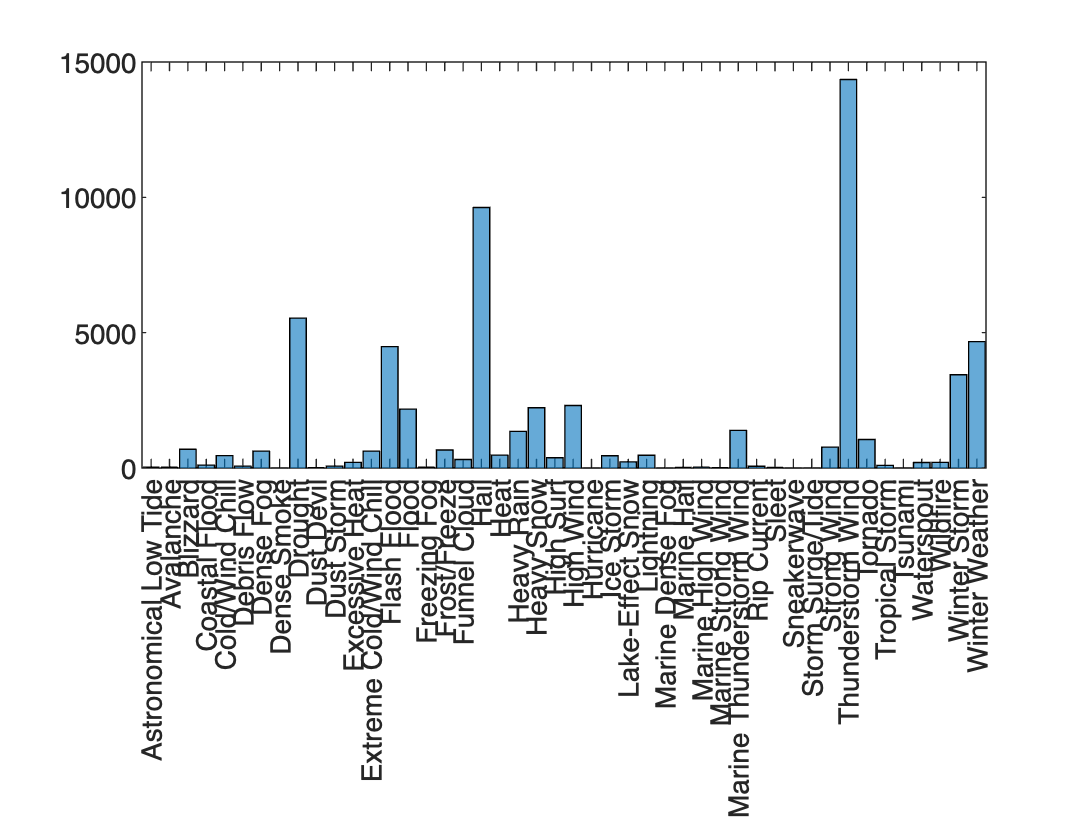

events.Total_cost = events.Property_Cost + events.Crop_Cost;
events = movevars(events, "Total_cost", "Before", "Begin_Lat");
histogram(events.Event_Type)

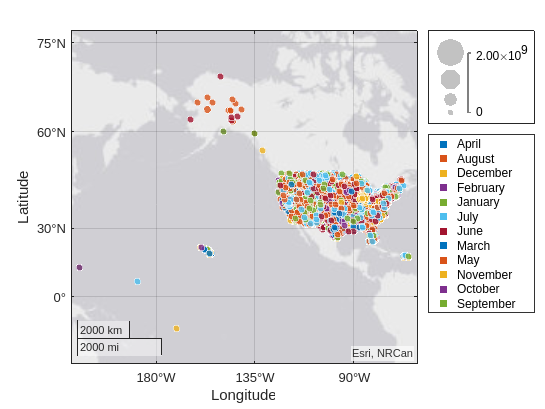

geobubble(events.Begin_Lat,events.Begin_Lon, events.Property_Cost, events.Month)

writetable(events, "StormEvents_2013_withTotalCost.csv")